# AM13x Motor Control Demo - Detailed Documentation

[Back to main page](matlab:open('../chapter_1_introduction/introduction_am13x.mlx'))

[Back to examples](matlab:open('.\examples_am13x.mlx'))

Sensorless Field-Oriented Control (FOC) for AM13x Microcontroller Family

## Overview

This documentation describes the sensorless Field-Oriented Control (FOC) motor control example for the AM13x microcontroller family. The example demonstrates a complete motor control workflow including simulation, code generation, hardware deployment, and runtime monitoring .

**Target Hardware:**

- **Microcontroller:** AM13E230x - TI's real-time MCU for motor control applications

- **Motor Driver:** DRV8323RS - Three-phase gate driver with integrated current sense amplifiers

- **Development Board:** AM13E230x LaunchPad

- **Motor:** Teknic M-2310P 

**Key Features:**

- Sensorless FOC implementation utilizing sliding mode observer

- Open-loop startup sequence with seamless transition to closed-loop operation

- Dual-loop control architecture (speed and current regulation)

- Serial communication interface for runtime monitoring and parameter tuning

- Code Composer Studio (CCS) integration for debugging capabilities

Additional Product Dependency:

- [Motor Control Blockset - MATLAB](https://in.mathworks.com/products/motor-control.html) for control algorithm and motor simulation.

## High-Level Model Overview

The model architecture adheres to a standard FOC structure with distinct algorithm and plant separation .

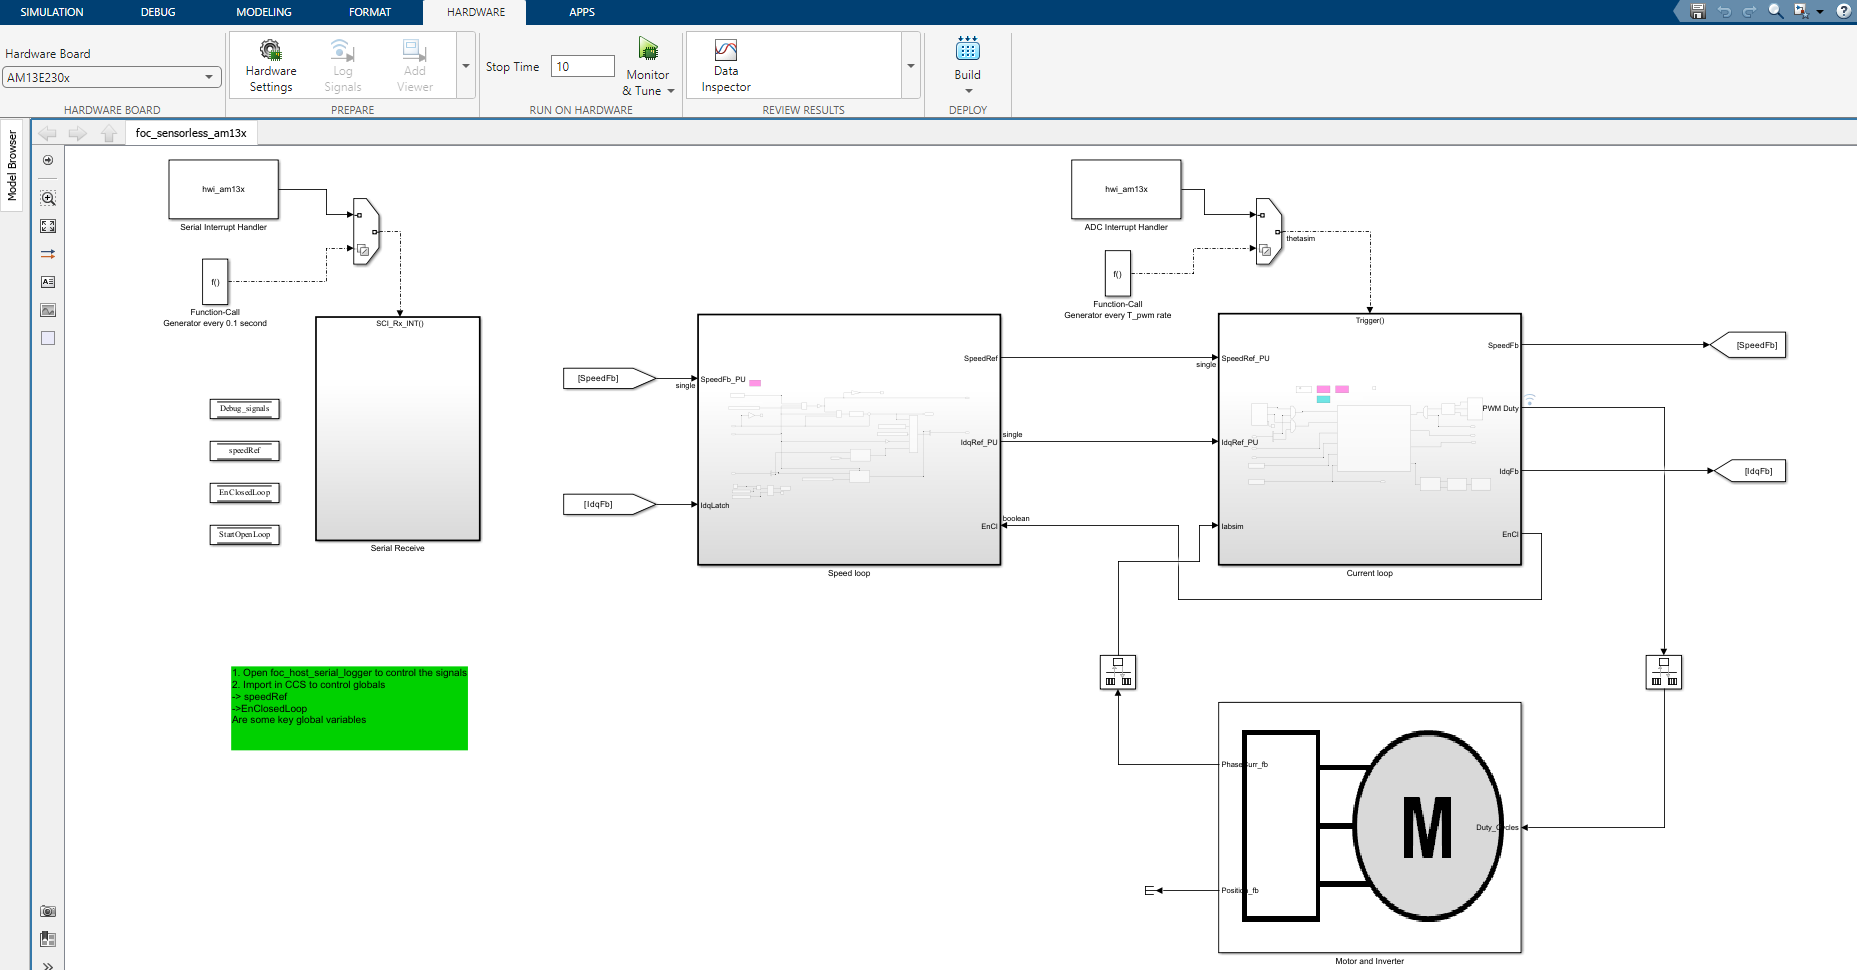

**Variant Subsystem Usage:**

- **Simulation Mode:** Both algorithm and plant subsystems (motor and inverter) are active during simulation

- **Code Generation Mode:** Only the algorithm subsystem is active; the plant subsystem is excluded from code generation

**Control Structure:**

- **Current Loop** - Inner control loop operating at PWM frequency (20 kHz nominal) implementing Clarke and Park transformations, PI controllers for Id and Iq currents, and Space Vector PWM generation

- **Speed Loop** - Outer control loop operating at a reduced rate, implementing PI controller for speed regulation and generating the Iq current reference

- **Sensorless Observer** - Estimates rotor position and speed using a sliding mode observer with Phase-Locked Loop (PLL) for position tracking

## **Signal Flow Architecture:**

    **ADC -> Current Sensing -> Clarke Transform -> Park Transform -> PI Controllers -> Inverse Park Transform -> Space Vector PWM -> PWM Duty Cycles**

## SysConfig Configuration

The hardware peripherals are configured using the TI SysConfig tool. The .syscfg file defines the peripheral initialization parameters as follows :

## ADC Configuration

- **ADC0** - Phase C current measurement

- **ADC1** - Phase B current measurement

- **ADC2** - Phase A current measurement

- **Sampling Rate:** Synchronized with PWM switching frequency (20 kHz)

- **Trigger Source:** MCPWM4 SOCA event

- **Resolution:** 12-bit analog-to-digital conversion

- **Reference Voltage:** Internal 3.3V reference

**Current Sensing Configuration:**

- DRV8323RS amplifier gain: 20 V/V (default, configured in hardware)

- Shunt resistor: As specified by inverter board design

- Offset calibration: Performed automatically during startup phase (first 1 second)

- Inverting amplifier effect is compensated by negating the sensed currents in the algorithm.

## PWM (MCPWM) Configuration

- **MCPWM4 Channels 1, 2, and 3** - Three-phase PWM signal generation

- **Switching Frequency:** 20 kHz (50 µs period)

- **Counting Mode:** Up-down count (symmetric PWM generation)

- **Deadband:** Configured according to gate driver requirements

- **ADC Trigger:** SOCA event generated when counter approaches zero, using CMPC comparator loaded with 10 counts 

## GPIO Configuration

- **Enable Pin:** DRV8323RS chip enable signal (configured as digital output)

- **Fault Pins:** DRV8323RS fault monitoring signals (configured as digital inputs)

- **LED:** Status indication output

## Interrupt Configuration

- **ADC0_INT1_INT** - Current loop execution interrupt (20 kHz) (Configured interrupt designation in SysConfig: MTR1_FOC_INT1) 

- **Timer Interrupt** - Speed loop execution interrupt (reduced rate, typically 1 kHz)

## Hardware Setup:

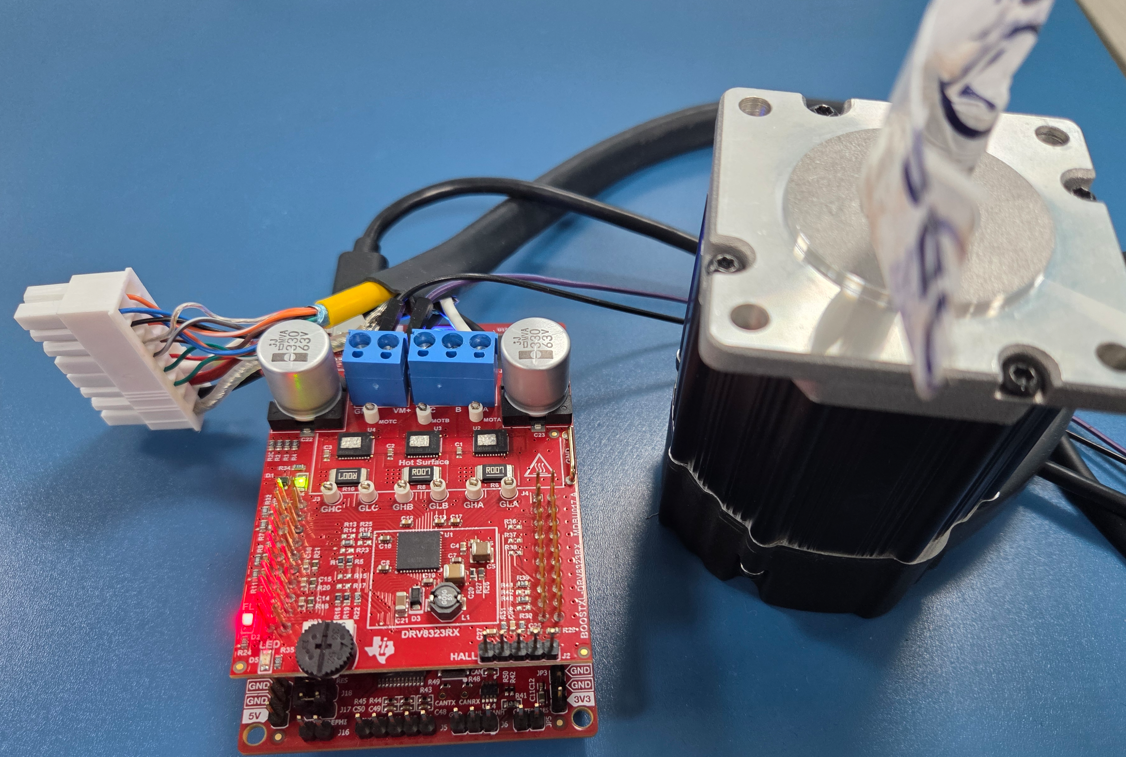

## Workflow Steps

## Step 1: Simulation

**Objective:** Validate the control algorithm prior to hardware deployment .

**Setup Procedure:** Open the motor control model and execute the initialization script:

% Motor parameters (Teknic M-2310P from Motor Control Blockset)
motor = mcb.internal.SetupMotor('Teknic2310P');

% Inverter parameters (customized for DRV8323RS board)
inverter = mcb.internal.SetupInverter();
inverter.Vdc = 24;       % DC bus voltage (V)
inverter.AdcGain = 20;   % DRV8323RS default gain setting

% Compute PI controller parameters
[currentPI, speedPI] = computePIParameters(motor, inverter);

**Simulation Configuration:**

- Solver Type: Fixed-step, ode3 (Bogacki-Shampine algorithm)

- Step Size: 50 µs (PWM period divided by 10)

**Expected Simulation Results:**

- **0-1 second:** Offset calibration phase (PWM disabled, speed maintained at zero)

- **1-2 seconds:** Open-loop startup sequence at low speed

- **2-5 seconds:** Open-loop speed ramp profile

- **5-10 seconds:** Closed-loop operation (enabled for simulation purposes)

**Signals to Monitor:**

- Speed reference versus feedback response

- Id and Iq current components

- Three-phase currents (Ia, Ib, Ic)

- PWM duty cycle outputs

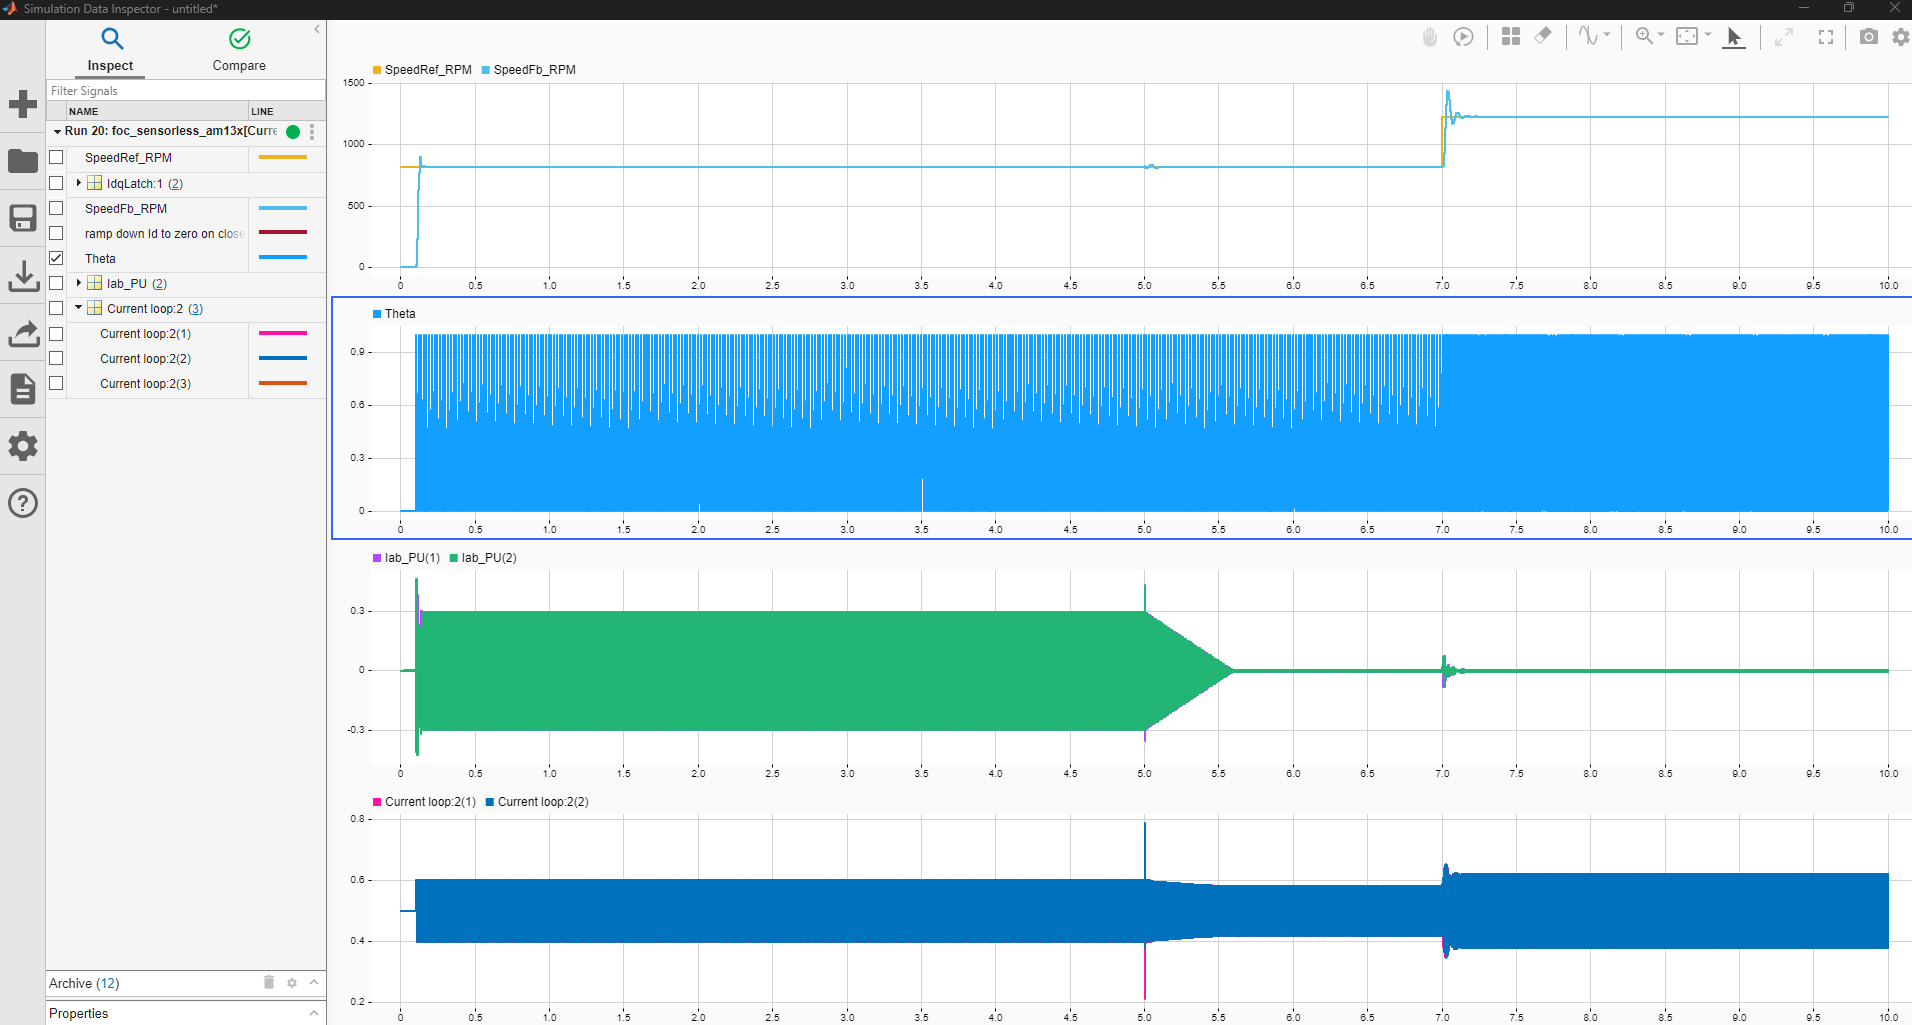

## Step 2: Code Generation and Build

**Objective:** Generate embedded C code and build the executable binary for the AM13x target platform .

**Configuration Procedure:**

- Select the hardware board in model configuration parameters: Navigate to Configuration Parameters → Hardware Implementation. Set Hardware board to:  `AM13E230X LaunchPad`

- Configure build settings:

**Code Generation Settings:**

- System target file: `ert.tlc` (Embedded Coder target)

- Toolchain: TI ARM Clang (configured via `setup_am13x()` function)

- Optimization Level: Speed optimization (`-O2` or `-O3` compiler flags)

- Code replacement library: TI ARM optimized function implementations

**Build Process Sequence:**

- SysConfig tool generates peripheral initialization code

- Simulink Coder generates algorithm C code

- Compiler: TI ARM Clang (version 4.0.4.LTS or later required)

- Linker: Utilizes SDK-provided linker command file

- Output: Executable `.out` file for target deployment

**Build Verification:**

- Review build log for compilation errors or warnings

- Verify executable size is within reasonable limits (< 100 KB for this example)

- Confirm absence of linker warnings regarding undefined symbols

## Step 3: Hardware Deployment and Monitoring

%%%% 3.1 Flash Executable to Target Hardware
% *Using Code Composer Studio (CCS):*
%
% # Import the project from the generated |CCS_Project| folder
% # Connect the LaunchPad development board via USB (XDS110 debugger interface)
% # Build and load the program to target memory
% # Execute the application
%
% *Using UniFlash (Alternative Method):*
%
% # Utilize the generated |.out| executable file
% # Flash the binary to target memory using UniFlash tool

%%%% 3.2 Host Model for Signal Monitoring
% *Objective:* Provide real-time visualization of motor control signals via
% serial communication interface .
%
% *Setup Procedure:* Open the host-side Simulink model: |foc_sensorless_am13x_host.slx|
%
% Configure serial port parameters:

% Default communication settings
COMPort  = 'COM7';
BaudRate = 5000000;  % 5 Mbps serial communication rate

**Signal Selection Options:** The target transmits configurable signal pairs via serial interface:

- Option 1: Speed reference and speed feedback signals

- Option 2: Id reference and Id feedback signals

- Option 3: Iq reference and Iq feedback signals

- Option 4: Phase currents (Ia and Ib)

**Execute Host Model:**

% Initiate serial communication
sim('foc_sensorless_am13x_host');

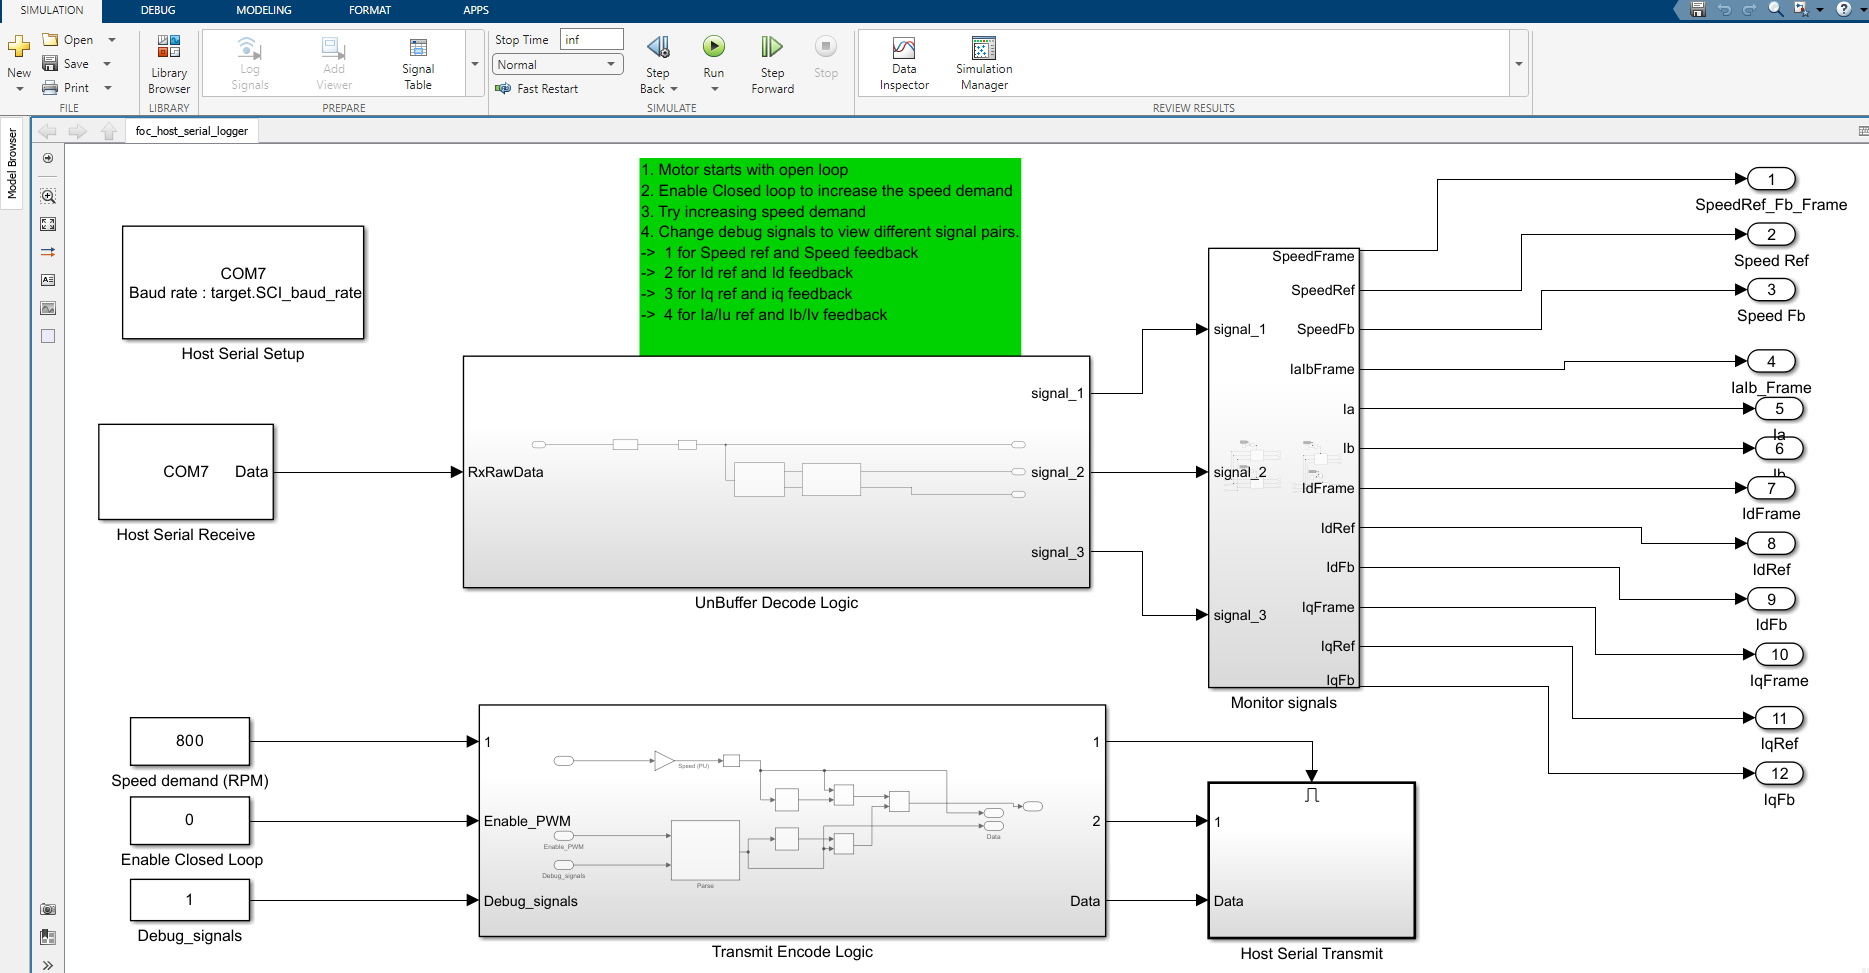

**Available Features:**

- **Non-buffered logging:** Low-rate data streaming for continuous monitoring

- **Buffered logging:** High-rate data acquisition with software buffer management

- **Live plots:** Real-time oscilloscope displays

- **Parameter tuning:** Runtime modification of speed reference and motor enable/disable

%%%% 3.3 CCS Debug and Variable Monitoring
% *Objective:* Provide low-level debugging capabilities and global variable 
% inspection .
%
% *Global Variables Available for Monitoring (C code implementation):*
%
%   // Runtime status variables
%   float    speedRef_rpm;        // Speed reference (RPM)
%   float    speedFeedback_rpm;   // Speed feedback (RPM)
%   uint32_t closedLoopEnable;    // Control mode: 0=open-loop, 1=closed-loop
%
%   // Offset calibration variables
%   float IaOffset;               // Phase A current offset value
%   float IbOffset;               // Phase B current offset value
%
%   // Performance monitoring metrics
%   uint32_t currentLoopTicks;    // Current loop execution time (CPU cycles)
%   uint32_t speedLoopTicks;      // Speed loop execution time (CPU cycles)
%
% *CCS Watch Window Configuration:*
%
% # Add the above variables to the Expressions view
% # Enable continuous refresh mode
% # Monitor variable values during runtime execution
%
% *Runtime Variable Modification:*
%
% # Pause program execution
% # Modify variable value (e.g., speedRef_rpm = 1500)
% # Resume program execution
% # Observe motor response to parameter change

## Open-Loop Startup and Transition

## Open-Loop Startup Mechanism

**Objective:** Reliably initiate motor rotation from standstill before engaging the sensorless observer .

**Phase 1: Forced Commutation (1-2 seconds)**

The controller forces the motor to rotate through the following mechanism:

- Fixed Vd injection: Minimum voltage magnitude to overcome static friction

- Ramping position: Synthetic electrical angle generation

- Space vector generation: Creates a rotating magnetic field

**Phase 2: Speed Ramp (2-5 seconds)**

Gradually increase motor speed to establish sufficient back-EMF for observer operation:

- Initial speed: Approximately 200 RPM

- Target speed: Approximately 800 RPM (user-configurable)

- Ramp rate: Smooth acceleration profile

**Rationale for Open-Loop Startup:**

- Sensorless observers require minimum rotational speed and back-EMF magnitude

- Eliminates the requirement for initial rotor position detection

- Provides robust startup across different motor types and parameters

## Closed-Loop Transition

**Transition Logic Implementation:**

When transitioning from open-loop to closed-loop operation (controlled by the `closedLoopEnable` flag) :

**1. Latch Id Current Value:**

**2. Ramp Down Id Current:**

This gradual reduction allows the observer to stabilize before full closed-loop operation.

**3. Initialize PI Controller Integrators:**

- **Speed PI Controller:** Initialize integrator state with current Iq value

- **Current PI Controllers:** Initialize integrator states with current Vd and Vq values

This initialization prevents integrator windup and eliminates output discontinuities.

**4.Requirements for Smooth Transition:**

- Observer must be operational during open-loop phase (tracking mode)

- Sufficient motor speed for reliable back-EMF detection

- Proper PI controller initialization to match current operating point

**Tuning Parameters:**

- `Id_rampdown_rate`: Controls transition smoothness (typical duration: 100 ms)

- `closedloop_speed_threshold`: Minimum speed requirement for transition (typical range: 500-800 RPM)

## Performance Metrics

**Execution Time (Current Loop):**

- Target Performance: Approximately 10 µs @ 200 MHz CPU frequency

- Current Performance: Approximately 16 µs (executing from Flash memory) 

- Optimization Opportunities: Utilize TMU (Trigonometric Math Unit) for sine/cosine calculations, replace lookup tables with direct TMU function calls, and execute ISR from RAM

**CPU Load Analysis:**

- Current loop @ 20 kHz: Approximately 30% CPU utilization (target: 20%) 

- Speed loop @ 1 kHz: Negligible CPU utilization

## Customization for Different Hardware

## Motor Parameters

To utilize a different motor, modify the initialization script as follows :

% Custom motor parameter configuration
motor       = mcb.internal.SetupMotor();
motor.p     = 4;          % Number of pole pairs
motor.Rs    = 0.285;      % Stator resistance (Ω)
motor.Ld    = 0.00032;    % d-axis inductance (H)
motor.Lq    = 0.00032;    % q-axis inductance (H)
motor.FluxPM= 0.0183;     % Permanent magnet flux linkage (Wb)
motor.J     = 7.061e-6;   % Rotor inertia (kg·m²)
motor.B     = 0;          % Viscous friction coefficient
motor.RatedSpeed = 4000;  % Rated operational speed (RPM)

## Inverter Board Parameters

For custom inverter board configurations :

% Custom inverter parameter configuration
inverter            = mcb.internal.SetupInverter();
inverter.Vdc        = 24;    % DC bus voltage (V)
inverter.AdcGain    = 20;    % Current sense amplifier gain (V/V)
inverter.Rshunt     = 0.01;  % Shunt resistance value (Ω)
inverter.Vref       = 3.3;   % ADC reference voltage (V)
inverter.MaxCurrent = 10;    % Maximum allowable phase current (A)

## Pin Configuration

Modify the SysConfig file (.syscfg) to configure the following :

- ADC channel pin assignments

- PWM output pin assignments

- GPIO pins for enable and fault signals

- UART pins for serial communication interface

## Troubleshooting

- Verify `closedLoopEnable = 0` (ensure startup in open-loop mode)

- Verify PWM signal generation using oscilloscope

- Verify DRV8323RS enable pin state is active

- Verify DC bus voltage is within specified range

**Transition to closed-loop operation fails:**

- Increase open-loop speed set speed before codegen for producing required boost voltage before initiating transition

- Adjust observer gain parameters

- Verify current sensing signal polarity is correct

- Verify Id ramp-down sequence is active during transition

**Excessive CPU load:**

- Enable compiler optimization flags

- Utilize TMU for trigonometric function calculations

- Reduce logging and diagnostic overhead

- Verify interrupt priority configuration

**Serial communication issues:**

- Verify COM port designation and baud rate settings

- Verify UART pin configuration in SysConfig

- Reduce data transmission rate if necessary

- Utilize buffered logging for high-rate signal acquisition

## References

- [AM13E23019 Product Page](https://www.ti.com/product/AM13E23019)

- [DRV8323R Product Page](https://www.ti.com/product/DRV8323R)

- AM13x MCU Software Development Kit (SDK) Documentation

- Motor Control Blockset Documentation (MathWorks)

- TI SysConfig User Guide

## Example Path:

**Simulink files: **  examples\motor_control\foc_sensorless_am13x.slx & examples\motor_control\foc_host_serial_logger.slx 

**SysCfg file:  **xamples\motor_control\foc_sensorless_am13x.syscfg

**Initialization script file:**   examples\motor_control\foc_sensorless_am13x_data.m

[Back to main page](matlab:open('../chapter_1_introduction/introduction_am13x.mlx'))

[Back to examples](matlab:open('.\examples_am13x.mlx'))